# Driver test program to check clothoid computation 

%=========================================================================%
%                                                                         %
%  Autors: Enrico Bertolazzi                                              %
%          Department of Industrial Engineering                           %
%          University of Trento                                           %
%          enrico.bertolazzi@unitn.it                                     %
%                                                                         %
%=========================================================================%

## Data XY for the clothoid

tol = 1e-10;

X = [2.9265642,2.6734362,2.5109322,1.9078122,1.1859282,1.9249962, ...
     2.8265562,0.00468420000000025,-2.826567,-1.9437558,-1.1859438, ...
     -1.9062558,-2.501565,-2.6734386,-2.9265642,-2.6187522,-1.1406318, ...
     -0.8968758,-1.4562558,-1.9062558,-0.00468780000000013,1.9078122, ...
     1.4468682,0.8968722,1.1406282,2.6187522, 2.9265642 ];
Y = [-1.707808758,-1.707808758,-2.367185958,-2.582810358,-2.582810358, ...
     -1.167184758,0.915619242,3.178123242,0.915619242,-1.150000758, ...
     -2.582810358,-2.582810358,-2.393750358,-1.707808758,-1.707808758, ...
     -3.178123242,-3.178123242,-2.989063158,-0.915616758,0.925003242, ...
     2.953123242,0.925003242,-0.915616758,-2.989063158,-3.178123242,-3.178123242, -1.707808758 ];

## Close all windows

close all;

## Initialize G2 clothoid spline object

S  = ClothoidSplineG2();
%S.ipopt(true);       if you have ipopt and not Optimization toolbox
%S.ipopt_check(true);

## Compute various G2 clothoid spline with different target

SPL = cell(8,1);

SPL{1} = S.buildP1( X, Y, -pi, -pi ); %3.141592653589793, 7.647610983392527 );


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           1         46.3737            58.3         0.01
     1           2       0.0736206            1.06        0.001         2.0438
     2           3     4.61299e-07          0.0024       0.0001      0.0659862
     3           4     1.64499e-16        4.02e-08        1e-05    0.000177337
     4           5     2.06332e-27         1.5e-13        1e-06     5.3719e-09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

SPL{3} = S.buildP3( X, Y, SPL{1}.thetaBegin(), SPL{1}.kappaBegin() );

SPL{1} = S.buildP1( X, Y, -pi/2, 0 ); %3.141592653589793, 7.647610983392527 );


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           1         47.5444            58.3         0.01
     1           2         3.29133            30.3        0.001        2.44354
     2           3     0.000593887           0.417       0.0001       0.130769
     3           4     1.31608e-11        6.07e-05        1e-05     0.00142426
     4           5      4.0791e-25        2.73e-12        1e-06    2.21292e-07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

SPL{2} = S.buildP2( X, Y );


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           1         50.1412            58.3         0.01
     1           2        0.202802            6.29        0.001        1.73487
     2           3     8.47412e-07         0.00874       0.0001      0.0619425
     3           4     1.81744e-16        1.46e-07        1e-05    0.000199672
     4           5     3.10873e-27        2.28e-13        1e-06    5.92593e-09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

SPL{4} = S.buildP4( X, Y );

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    1.100679e+03     3.121e+00     1.000e+00     0.000e+00     6.159e+03  
    1           3    5.163633e+01     3.292e+00     1.000e+00     4.735e+00     4.087e+03  
    2           7    1.667105e+02     1.431e+00     4.900e-01     3.661e-01     1.940e+03  
    3           9    2.525539e+02     3.411e-02     1.000e+00     2.999e-01     1.237e+02  
    4          11    2.492287e+02     4.419e-05     1.000e+00     4.048e-03     1.808e+00  
    5          13    2.492244e+02     7.472e-11     1.000e+00     4.597e-06     1.653e-13  

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the cu

SPL{5} = S.buildP5( X, Y );

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    1.805249e+00     3.121e+00     1.000e+00     0.000e+00     1.398e-01  
    1           3    1.784499e+00     5.763e-02     1.000e+00     9.938e-01     4.436e-01  
    2           5    1.782205e+00     1.933e-04     1.000e+00     5.857e-02     3.695e-02  
    3           7    1.779617e+00     5.925e-04     1.000e+00     9.350e-02     1.628e-02  
    4           9    1.778934e+00     4.838e-04     1.000e+00     7.659e-02     5.711e-03  
    5          11    1.778902e+00     1.751e-05     1.000e+00     7.885e-03     5.435e-03  
    6          14    1.778710e+00     2.434e-07     1.000e+00     3.797e-02     4.026e-03  
    7          17    1.778466e+00     1.333e-05     1.000e+00     1.078e-01     4.123e-04  
    8          19    1.778466e+00     4.399e-07     1.000e+00     1.868e-03     6.

SPL{6} = S.buildP6( X, Y );

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    4.266085e+01     3.121e+00     1.000e+00     0.000e+00     4.105e-01  
    1           3    4.314519e+01     5.760e-02     1.000e+00     9.915e-01     2.258e-01  
    2           5    4.316440e+01     2.330e-04     1.000e+00     4.371e-02     2.892e-02  
    3           7    4.316268e+01     7.710e-04     1.000e+00     6.285e-02     2.420e-02  
    4           9    4.315765e+01     6.779e-03     1.000e+00     2.785e-01     9.646e-03  
    5          11    4.315667e+01     2.944e-03     1.000e+00     1.721e-01     7.505e-03  
    6          13    4.315660e+01     1.986e-06     1.000e+00     8.886e-03     5.859e-03  
    7          15    4.315653e+01     1.654e-05     1.000e+00     2.285e-02     4.067e-04  
    8          17    4.315653e+01     3.015e-08     1.000e+00     4.378e-04     7.

SPL{7} = S.buildP7( X, Y );

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    5.083686e+01     3.121e+00     1.000e+00     0.000e+00     5.831e+00  
    1           3    6.714543e+01     3.292e+00     1.000e+00     3.735e+00     1.375e+01  
    2           6    7.035414e+01     6.206e-01     7.000e-01     1.131e+00     8.033e+00  
    3           8    7.142448e+01     1.255e-02     1.000e+00     8.484e-02     1.268e+00  
    4          10    7.138471e+01     1.380e-04     1.000e+00     9.419e-02     6.705e-01  
    5          12    7.138465e+01     5.567e-07     1.000e+00     4.652e-03     1.238e-03  
    6          14    7.138465e+01     1.082e-10     1.000e+00     6.544e-05     3.004e-06  
    7          16    7.138465e+01     1.243e-14     1.000e+00     2.148e-11     2.081e-07  



SPL{8} = S.buildP8( X, Y );

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    7.991375e+02     3.121e+00     1.000e+00     0.000e+00     1.569e+03  
    1           3    2.862206e+02     3.292e+00     1.000e+00     4.735e+00     1.062e+03  
    2           6    3.981669e+02     6.198e-01     7.000e-01     1.468e+00     5.004e+02  
    3          12    4.045963e+02     5.939e-01     2.401e-01     7.712e-01     3.880e+02  
    4          14    4.295361e+02     6.691e-02     1.000e+00     5.007e-01     7.269e+00  
    5          16    4.288640e+02     4.047e-02     1.000e+00     4.381e-01     2.939e+00  
    6          18    4.289357e+02     6.757e-05     1.000e+00     3.374e-02     9.088e-01  
    7          20    4.289353e+02     4.834e-05     1.000e+00     1.670e-02     3.030e-01  
    8          22    4.289353e+02     5.257e-06     1.000e+00     5.494e-03     5.

SPL{9} = S.buildP9( X, Y );

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    1.367079e+03     3.121e+00     1.000e+00     0.000e+00     1.742e+03  
    1           7    9.916207e+02     2.370e+00     2.401e-01     1.137e+00     1.385e+03  
    2           9    7.652644e+02     1.107e+00     1.000e+00     2.571e+00     6.529e+02  
    3          11    7.473761e+02     7.053e-02     1.000e+00     3.804e-01     1.805e+02  
    4          13    7.455136e+02     2.018e-04     1.000e+00     3.862e-02     1.734e+01  
    5          15    7.454681e+02     5.644e-06     1.000e+00     5.615e-03     4.014e-01  
    6          17    7.454681e+02     1.584e-10     1.000e+00     2.841e-05     1.484e-03  
    7          19    7.454681e+02     1.332e-14     1.000e+00     8.175e-12     2.447e-04  



## Plot results

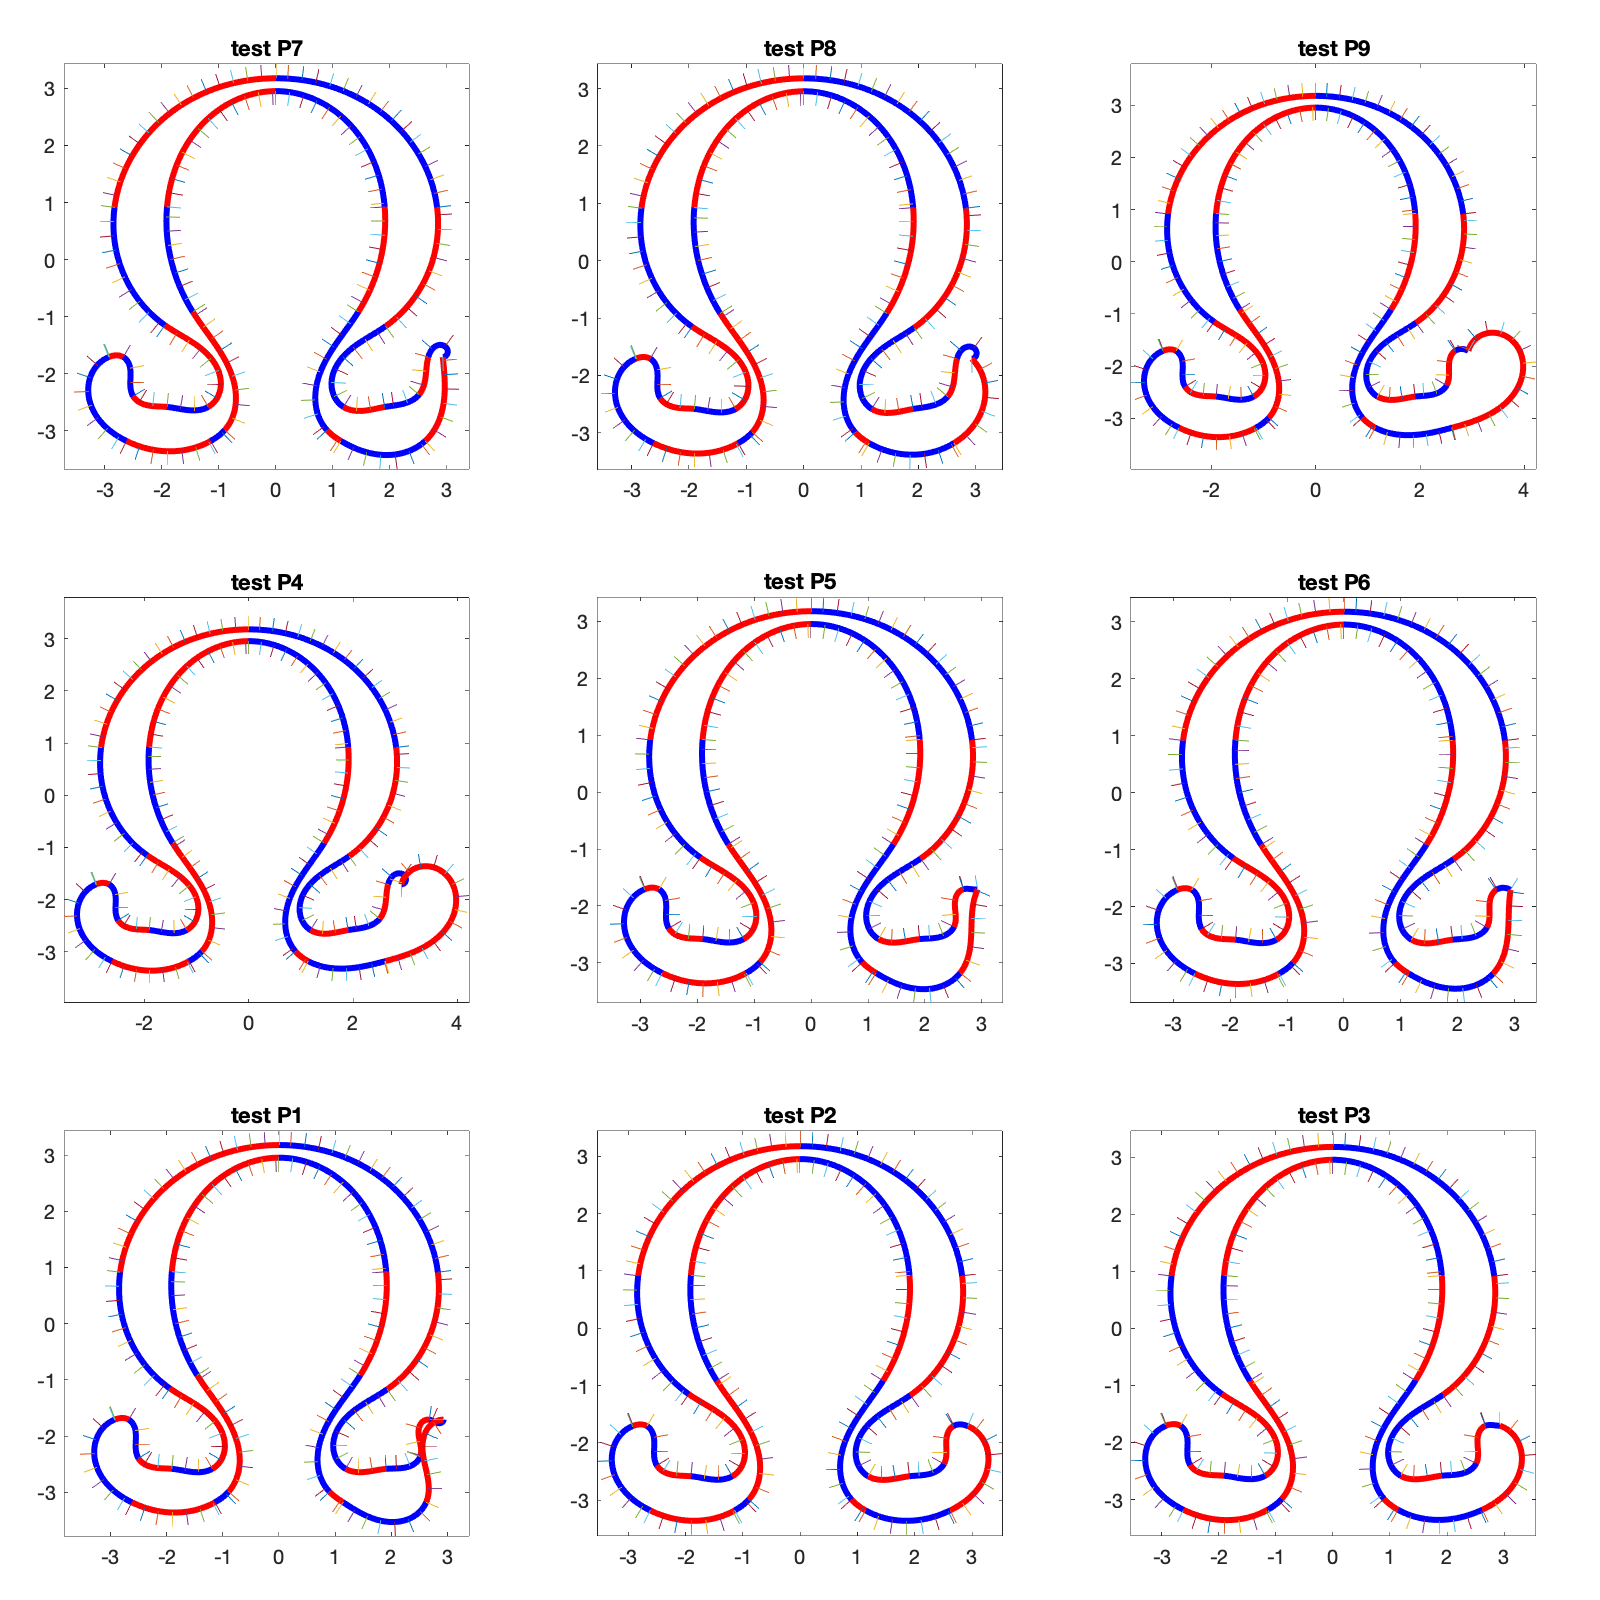

aa = 0.04;
bb = 1/3-2*aa;

figure('Position',[ 1 1 800 800]);

for k=1:9
  switch(k)
  case 1; subplot('Position',[aa     aa     bb bb]);
  case 2; subplot('Position',[aa+1/3 aa     bb bb]);
  case 3; subplot('Position',[aa+2/3 aa     bb bb]);
  case 4; subplot('Position',[aa     aa+1/3 bb bb]);
  case 5; subplot('Position',[aa+1/3 aa+1/3 bb bb]);
  case 6; subplot('Position',[aa+2/3 aa+1/3 bb bb]);
  case 7; subplot('Position',[aa     aa+2/3 bb bb]);
  case 8; subplot('Position',[aa+1/3 aa+2/3 bb bb]);
  case 9; subplot('Position',[aa+2/3 aa+2/3 bb bb]);
  end
  
  % subplot(3,3,k);
  SPL{k}.plot();
  SPL{k}.plotNormal(0.25,0.25);

  if k == 3
    hold on
    SPL{2}.plot(1000,{'Color','red','LineWidth',1},{'Color','blue','LineWidth',1});
  end

  title(sprintf('test P%d',k));

  axis equal;
end